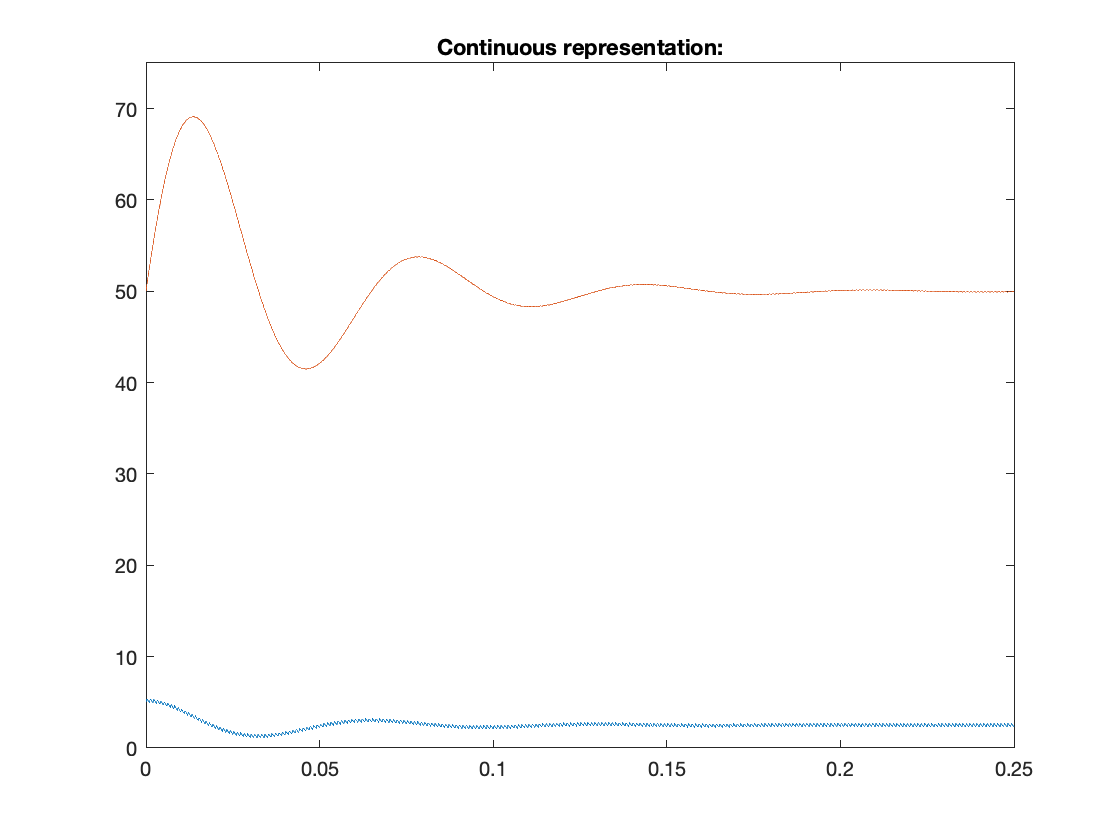

%%Case 2
%%Buck Converter, Resistance increment (10Ohm to 20Ohm)
%
L_1=100e-03; %Coil
C=1000e-06; %Capacitor
R=20; %Resistance
T=0.001; %Duty cycle
V=200; %V_input
time=1.2;%Duration of the control action simmulation
A=[0 -1/L_1; 1/C -1/R/C]; %State matrix "Buck Converter"
B=[V/L_1; 0]; %Input matrix
V_o=50;
I_o=5; %At 10OHm
V_f=50;
I_f=2.3125; %At 20Ohm - this value is T dependant, take it into account when changing T.
%Some reference values: With T=0.001/I_f=2.3125 ; T=0.005/I_f=1.5590
%;T=0.01/If=0.5973
%
%Continuous representation
%
Td=T/4000;
N=1000*(time/T);
delta=0.25;
x=zeros(2,N);
x(:,1)=[I_o;V_o];
for i=1:N+1
    if (mod(i,4000)/4000<delta)
       x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
    else
       x(:,i+1)=x(:,i)+ Td*A*x(:,i);
    end
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x')
title('Continuous representation:')
ylim([0 75])
xlim([0 0.25])

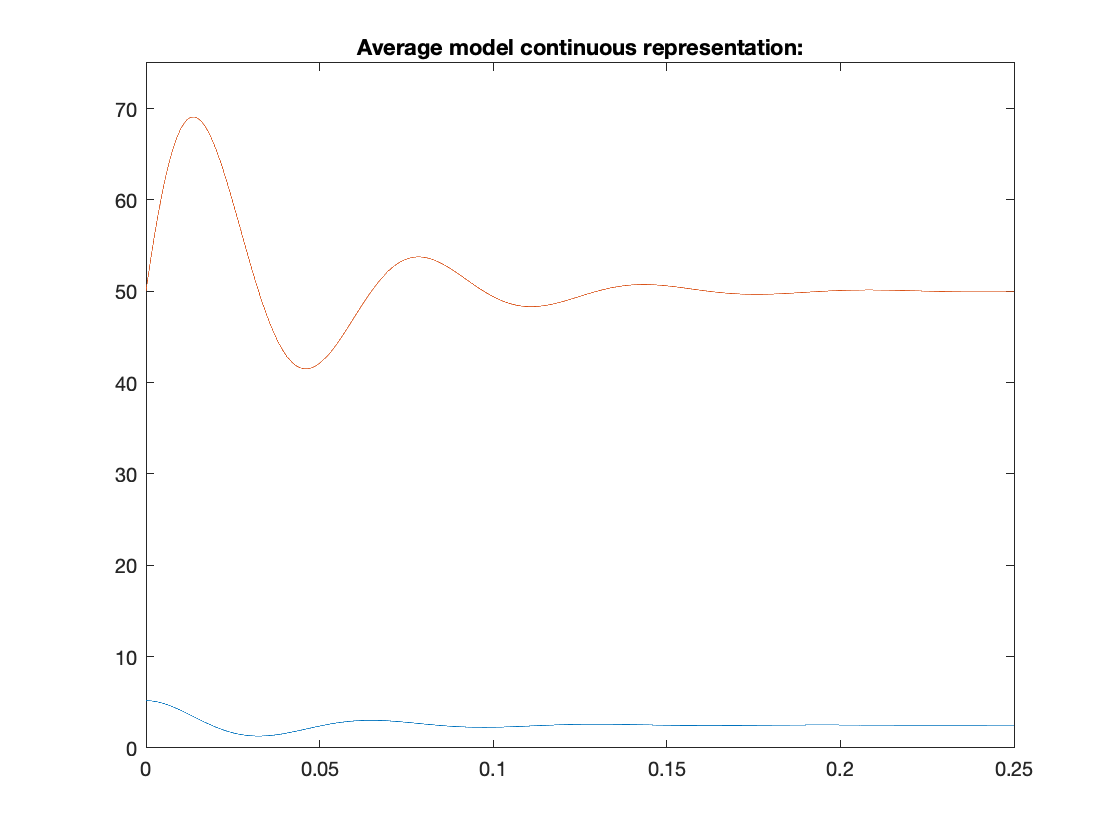

%Averaged model
in_est=[];
for i=1:T/Td
    in_est=[in_est x(1,i)];    
end
i_m=sum(in_est)/(T/Td);
%Then
A_avg=[0 -1/L_1; 1/C -1/R/C];
B_avg=[V*delta/L_1; 0];
%From this point, delta is not relevant, since the model is averaged for
%the full period T.
%Discretization.
x_avg=zeros(2,N);
x_avg(:,1)=[i_m;V_o];
for i=1:N+1
    x_avg(:,i+1)=x_avg(:,i)+Td*(A_avg*x_avg(:,i)+B_avg);
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
figure
t_avg=[0 (1:N+1)*Td];
plot(t_avg,x_avg')
title('Average model continuous representation:')
ylim([0 75])
xlim([0 0.25])

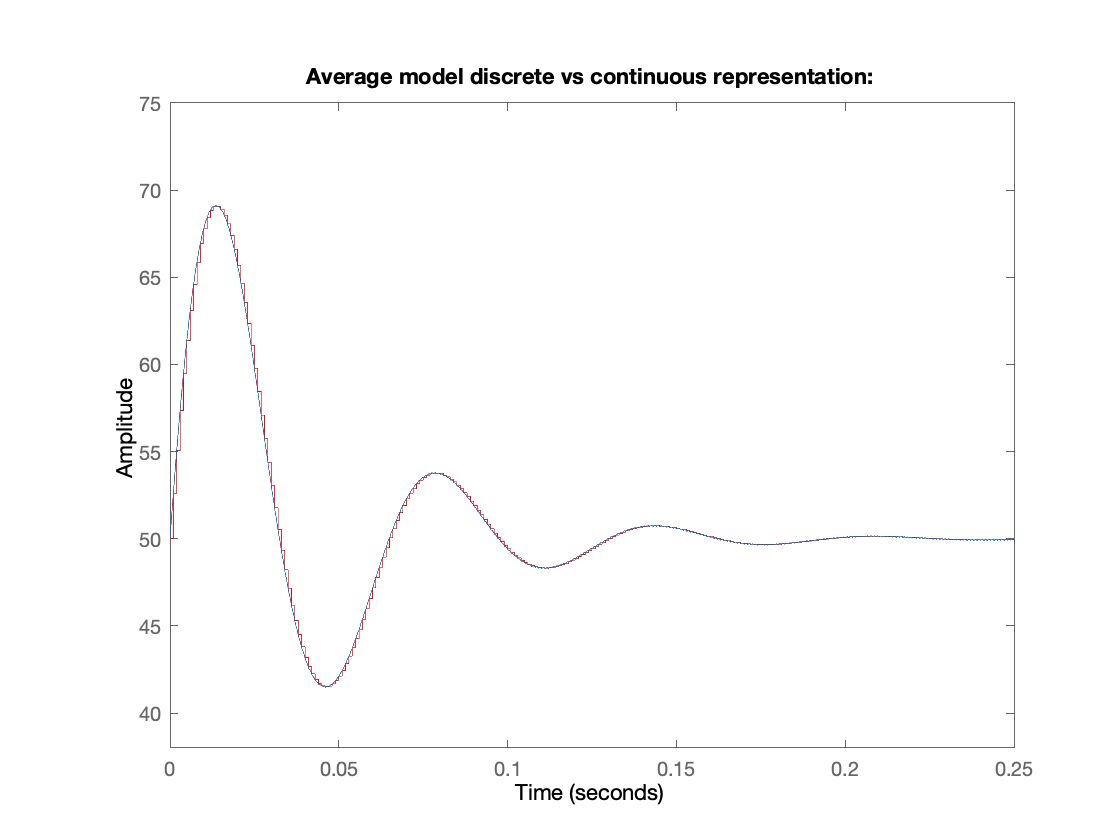

%Average model discrete
AVG=ss(A_avg,B_avg,[0,1],0);
Hd=c2d(AVG,T);
[Ad,Bd,Cd,Dd] = ssdata(Hd);
xd=zeros(length(A),N);
xd(:,1)=[I_o;V_o];
for i=1:length(xd)+1
    xd(:,i+1)=Ad*xd(:,i)+Bd;
end
TT=0:T:time;
U=ones(length(TT),1);
lsim(Hd,U,TT,[i_m;V_o],'red')
hold on
plot(t,x(2,:)')
title('Average model discrete vs continuous representation:')
hold off
ylim([38 75])
xlim([0 0.25])

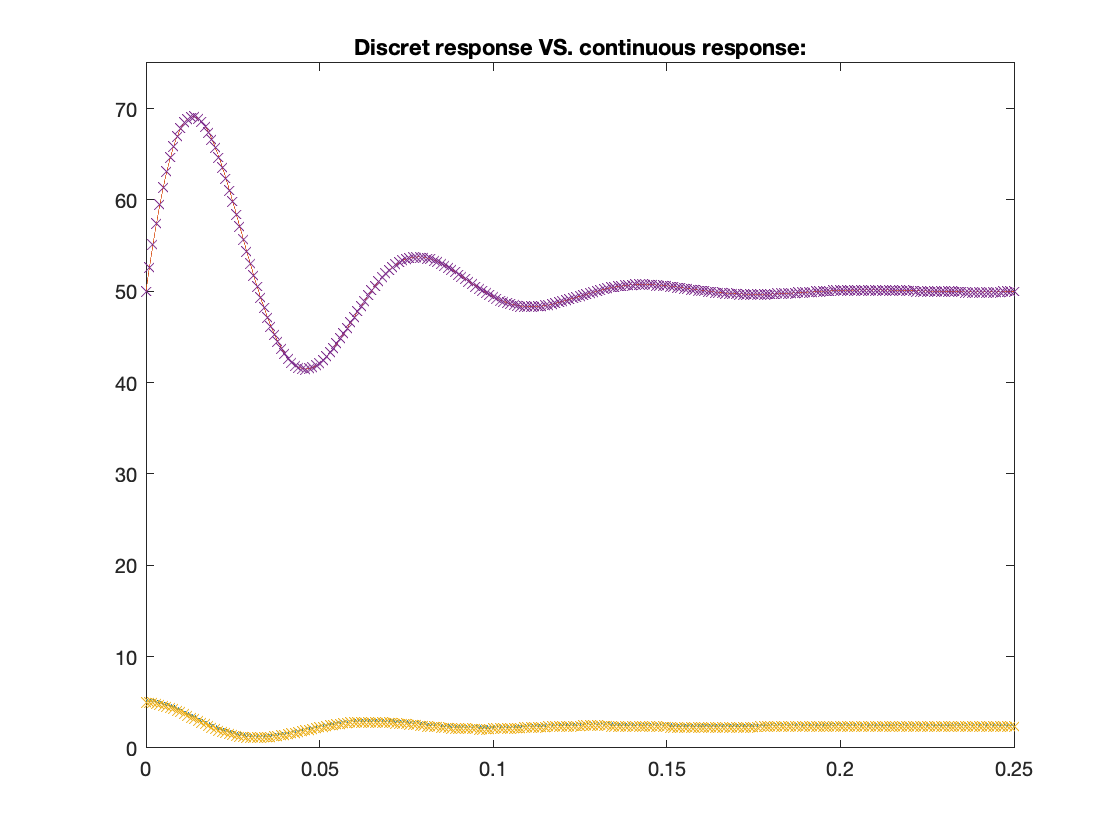

%First part has to be executed in order to solve this one.
%
%%Discrete representation.
%
%
[PA,PB,alpha2]=discrete_binary_f(A,B,T); %Fuzzy binary discretization function
%%%%%%%
N=50*20; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=[I_o,V_o]'; %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
t2=[0 (1:N+1)*T];
figure
plot(t,x') 
hold on
plot(t2,x2','x')
hold off
title('Discret response VS. continuous response:')
ylim([0 75])
xlim([0 0.25])

%Controller design 1, no input limit, no decay rate.
[V,D]=eig(A);
r=rank(A);
n=length(D);
x0=[I_o,V_o]';
x_f=[I_f,V_f]';
%%LMI optimization:
X1=sdpvar(n);
LMI1=[X1>=1e-8];
for i=1:PB.num_coef
    M1{i}=sdpvar(1,n);
end
PM1=MDCHP(ones(1,n),2*ones(1,n),M1);
PQR1=[X1 X1*PA'+PM1'*PB';PA*X1+PB*PM1 X1];
PQR1.Polya([4 4 4 4]);
coef1=PQR1.coef;
for i=1:length(coef1)
    LMI1=[LMI1 coef1{i}>=1e-8];
end
optimize(LMI1);

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 26              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.01    
Problem
  Name   

K1=double(PM1)*inv(double(X1));

%Controller design 2, input limit, no decay rate.
[V,D]=eig(A);
r=rank(A);
n=length(D);
x0=[I_o,V_o]';
x_f=[I_f,V_f]';
%%LMI optimization:
X2=sdpvar(n);
LMI2=[X2>=1e-8];
for i=1:PB.num_coef
    M2{i}=sdpvar(1,n);
end
PM2=MDCHP(ones(1,n),2*ones(1,n),M2);
PQR2=[X2 X2*PA'+PM2'*PB';PA*X2+PB*PM2 X2];
PQR2.Polya([4 4 4 4]);
coef2=PQR2.coef;
for i=1:length(coef2)
    LMI2=[LMI2 coef2{i}>=1e-8];
end
LMI2=[ LMI2 [1 x0';x0 X2]>=1e-8];
for i=1:length(M2)
    LMI2=[LMI2, [X2 M2{i}';M2{i} 1]>=1e-8]; 
end
optimize(LMI2);

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 31              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

K2=double(PM2)*inv(double(X2));

%Controller design 3, input limit, decay rate.
[V,D]=eig(A);
r=rank(A);
n=length(D);
x0=[I_o,V_o]';
x_f=[I_f,V_f]';
for i=1:PB.num_coef
    M{i}=sdpvar(1,n);
end
%LMI optimization:
dec_reg=[];
reg=[];
n_reg=[0];
decay = 1.0;
%Iterative procedure to find the minimum decay rate (30 steps)
for i=1:30
    PM=MDCHP(ones(1,n),2*ones(1,n),M);%
    X=sdpvar(n);
    PQ=[(decay^2)*X X*PA'+PM'*PB';PA*X+PB*PM X];
    PQR=PQ;
    PQR.Polya([4 4 4 4]);
    coef=PQR.coef;
    LMI=[ X>=0, [1 x0';x0 X]>=1e-8];
    for i=1:length(M)
        LMI=[LMI, [X M{i}';M{i} 1]>=1e-8]; 
    end
    for i=1:length(coef)
        LMI=[LMI coef{i}>=1e-8];
    end
    optimize(LMI);
    if ans.problem==0
        dec_reg=[dec_reg decay];
        reg=[reg decay];
        decay=(decay+max(n_reg))/2 ;
    else
        reg=[reg decay];
        n_reg=[n_reg decay];
        decay=(min(dec_reg)-max(n_reg))/2+max(n_reg);
    end
end

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 31              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

decay= min(dec_reg);
PM=MDCHP(ones(1,n),2*ones(1,n),M);%
X=sdpvar(n);
PQ=[(decay^2)*X X*PA'+PM'*PB';PA*X+PB*PM X];
PQR=PQ;
PQR.Polya([4 4 4 4]);
coef=PQR.coef;
LMI=[ X>=0, [1 x0';x0 X]>=1e-8];
for i=1:length(M)
    LMI=[LMI, [X M{i}';M{i} 1]>=1e-8]; 
end
for i=1:length(coef)
    LMI=[LMI coef{i}>=1e-8];
end
optimize(LMI);

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 31              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

dec_reg;
reg;
format long;
Decay_rate_case_2=min(dec_reg)

Decay_rate_case_2 =    0.886448306962848


format;
K3=double(PM)*inv(double(X));

%Controller design 4, no input limit, manually defined decay rate.
[V,D]=eig(A);
r=rank(A);
n=length(D);
x0=[I_o,V_o]';
x_f=[I_f,V_f]';
%decay= 0.3499675 %This decay only works at T=0.001, other cases may be unstable.
%%LMI optimization:
decay=0.35;
X4=sdpvar(n);
LMI4=[X4>=1e-8];
for i=1:PB.num_coef
    M4{i}=sdpvar(1,n);
end
PM4=MDCHP(ones(1,n),2*ones(1,n),M4);
PQR4=[(decay^2)*X4 X4*PA'+PM4'*PB';PA*X4+PB*PM4 X4];
PQR4.Polya([4 4 4 4]);
coef4=PQR4.coef;
for i=1:length(coef4)
    LMI4=[LMI4 coef4{i}>=1e-8];
end
optimize(LMI4);

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 26              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

K4=double(PM4)*inv(double(X4));

%Results:
%Controller iterative result for each period of time:
%Design 1
x3=zeros(n,time/T);
x3(:,1)=x0;
muT3=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x3)
    Ki=K1*(x3(:,i)-x_f)+0.25;
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT3=[muT3 delta];
    x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;
end
%
%
%Design 2
%
%
x4=zeros(n,time/T);
x4(:,1)=x0;
muT4=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x4)
    Ki=K2*(x4(:,i)-x_f)+0.25;
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT4=[muT4 delta];
    x4(:,i+1)=PA*x4(:,i)+PB.eval(alpha)*delta;
end
%
%
%Design 3
%
%
x5=zeros(n,time/T);
x5(:,1)=x0;
muT5=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x5)
    Ki=K3*(x5(:,i)-x_f)+0.25;
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT5=[muT5 delta];
    x5(:,i+1)=PA*x5(:,i)+PB.eval(alpha)*delta;
end
%
%
%Design 4
%
%
x6=zeros(n,time/T);
x6(:,1)=x0;
muT6=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x6)
    Ki=K4*(x6(:,i)-x_f)+0.25;
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT6=[muT6 delta];
    x6(:,i+1)=PA*x6(:,i)+PB.eval(alpha)*delta;
end

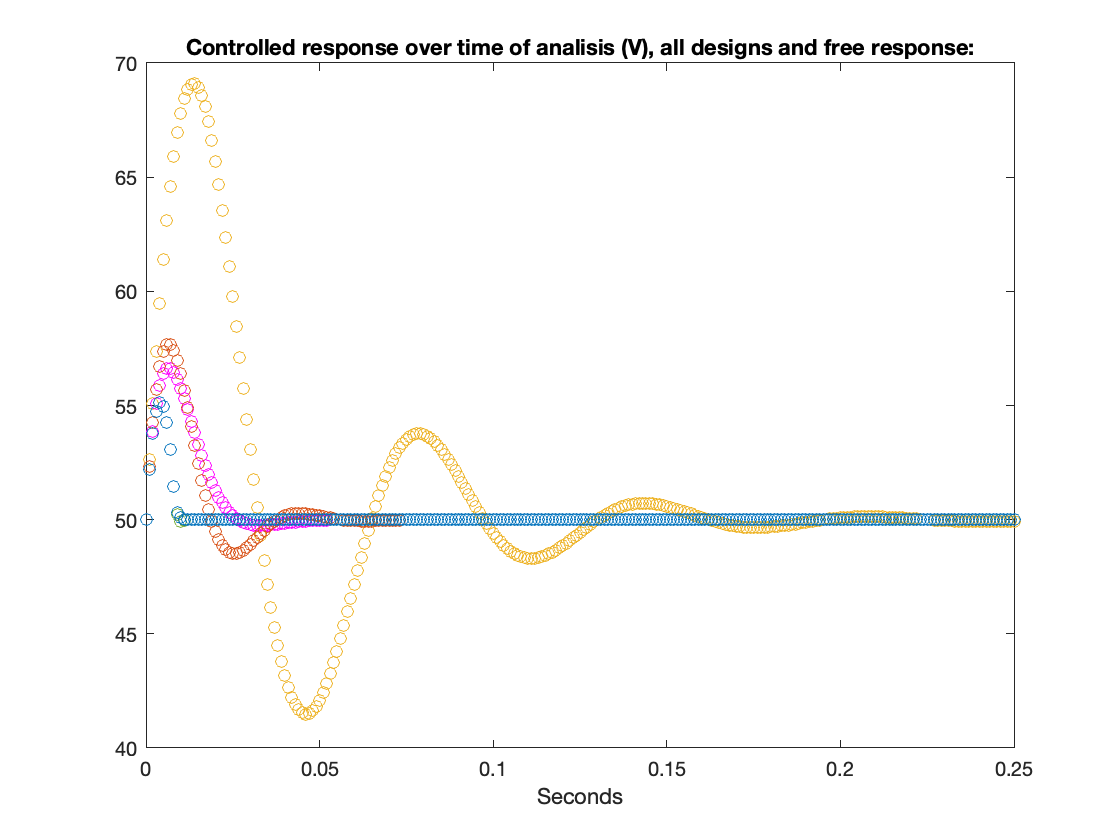

%Ploting
%
%
t3=[0 (1:i)*T];
figure
plot(t2,x2(2,:)','o','Color','#EDB120')%Yellow-Discrete free response
hold on
plot(t3,x6(2,:)','o','Color','#77AC30')%Green-Controller design 4 \ only decay rate
plot(t3,x5(2,:)','o','Color','magenta')%Magenta-Controller design 3 \ input limit+decay
plot(t3,x4(2,:)','o','Color','#D95319')%Red-Controller design 2 \ input limit
plot(t3,x3(2,:)','o','Color','#0072BD')%Blue-Controller design 1 \ no input limit, no decay rate
hold off
title('Controlled response over time of analisis (V), all designs and free response:')
xlabel('Seconds')
ylim([40 70])
xlim([0 0.25])

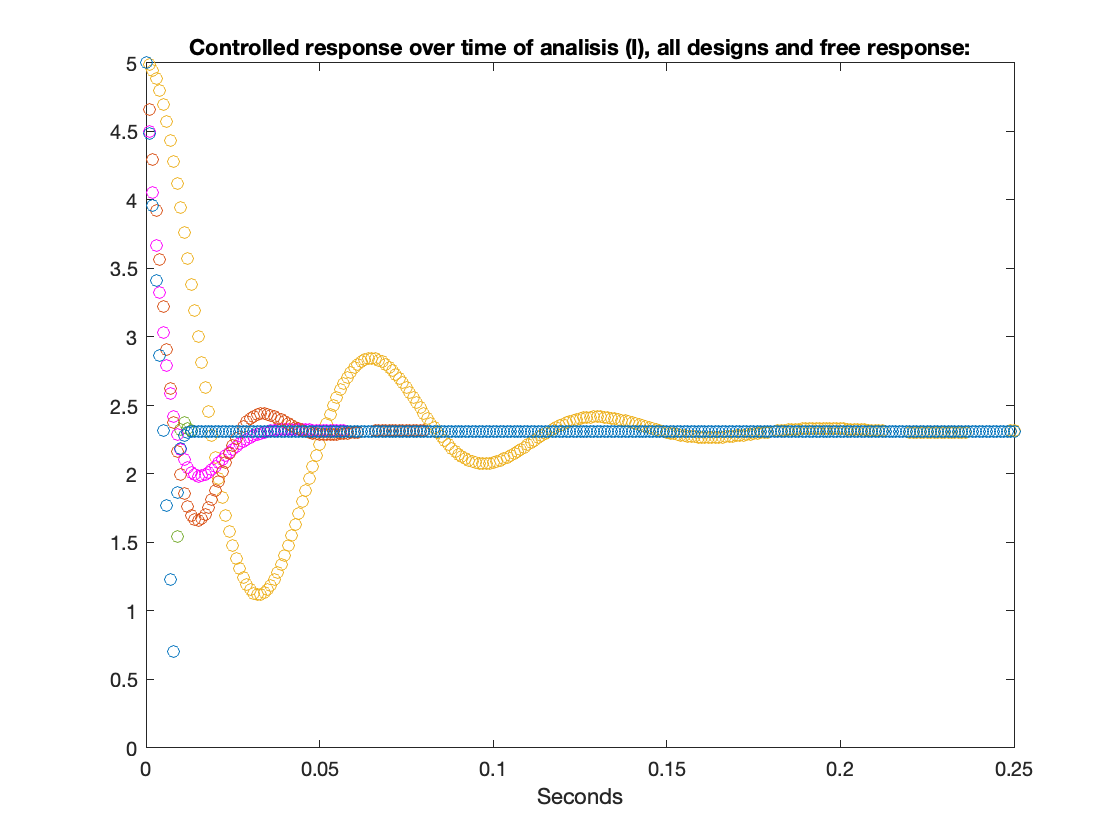

figure
plot(t2,x2(1,:)','o','Color','#EDB120')%Yellow-Discrete free response
hold on
plot(t3,x6(1,:)','o','Color','#77AC30')%Green-Controller design 4
plot(t3,x5(1,:)','o','Color','magenta')%Magenta-Controller design 3
plot(t3,x4(1,:)','o','Color','#D95319')%Red-Controller design 2
plot(t3,x3(1,:)','o','Color','#0072BD')%Blue-Controller design 1
hold off
title('Controlled response over time of analisis (I), all designs and free response:')
xlabel('Seconds')
ylim([0 5])
xlim([0 0.25])

figure
t4=[0 (1:length(muT3)-1)*T];
plot(t4,muT6','o','Color','#77AC30')%Green-Controller design 4
hold on
plot(t4,muT5','o','Color','magenta')%Magenta-Controller design 3
plot(t4,muT4','o','Color','#D95319')%Red-Controller design 2
plot(t4,muT3','o','Color','#0072BD')%Blue-Controller design 1
hold off
title('Control action over the time of analisis, all designs and free response:')
xlabel('Seconds')
format long;
Max_control_action_design_1=max(muT3)

Max_control_action_design_1 =    0.830894897059907


Max_control_action_design_2=max(muT4)

Max_control_action_design_2 =    0.281141210195959


Max_control_action_design_3=max(muT5)

Max_control_action_design_3 =    0.269231439561873


Max_control_action_design_4=max(muT6)

Max_control_action_design_4 =    0.670994819937279


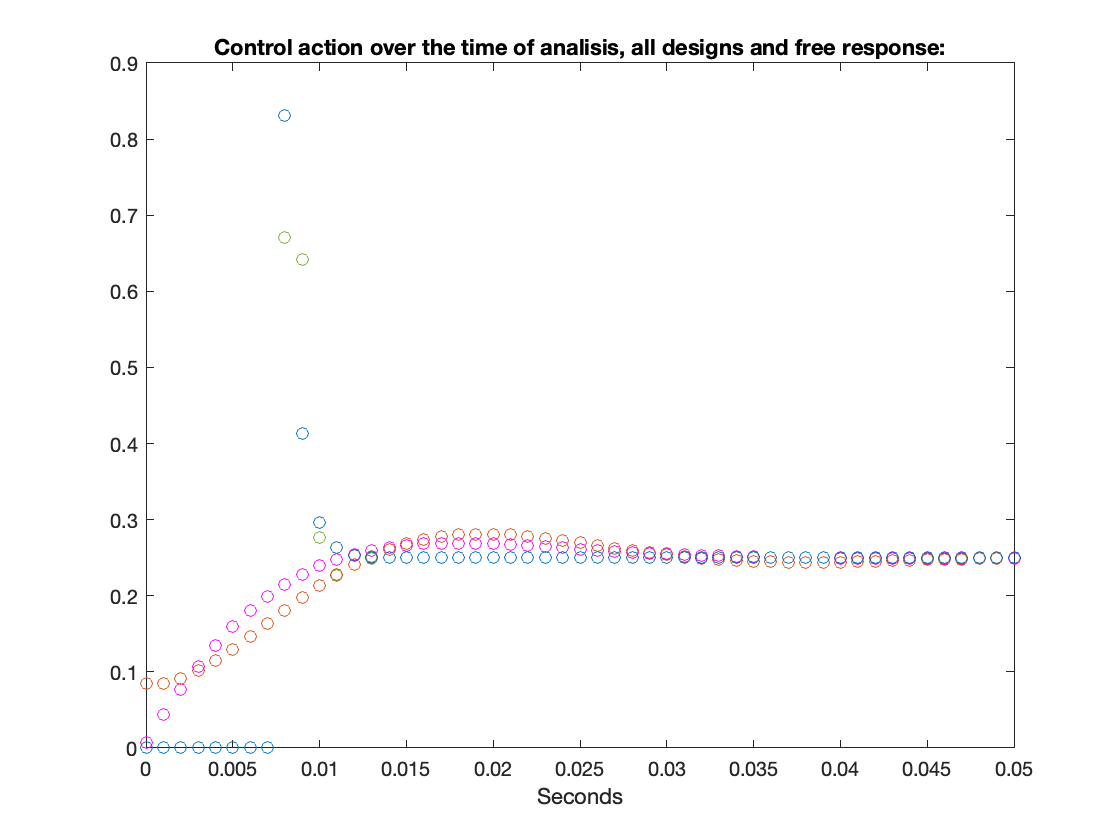

format;
ylim([0 0.9])
xlim([0 0.05])

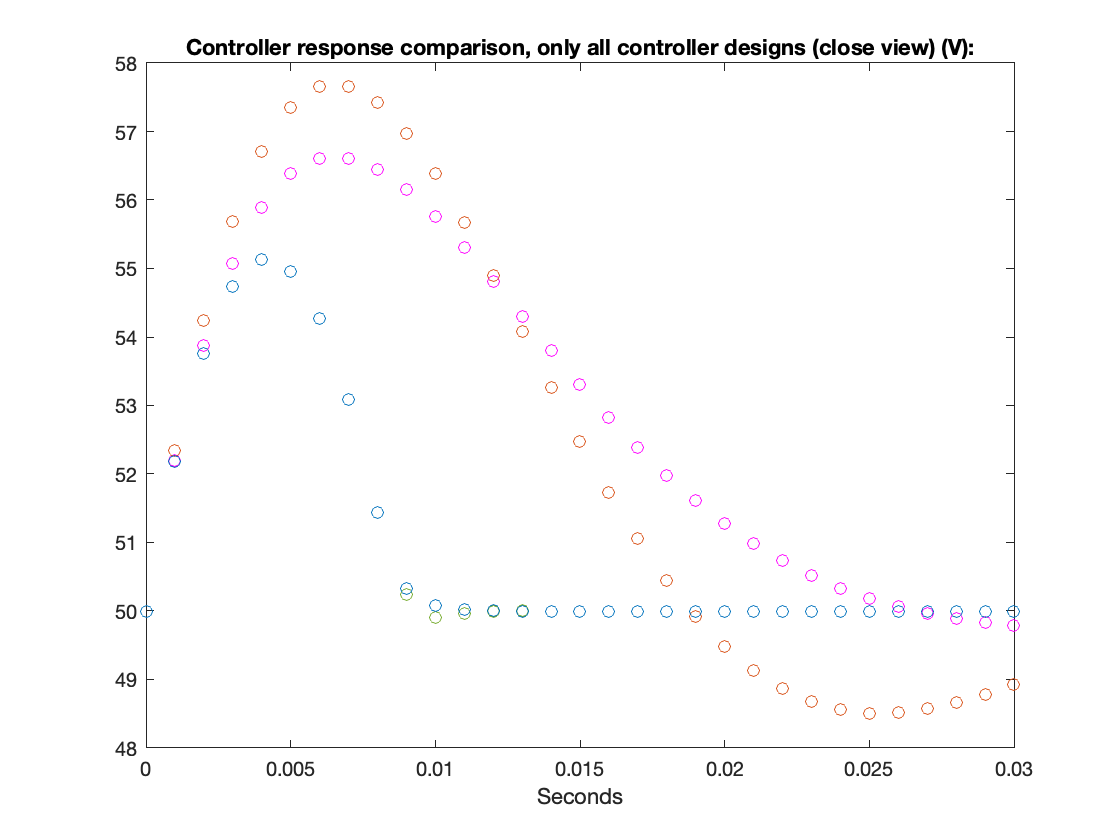

%
%
figure
plot(t3,x6(2,:)','o','Color','#77AC30')%Green-Controller design 4 \ only decay rate
hold on
plot(t3,x5(2,:)','o','Color','magenta')%Magenta-Controller design 3 \ input limit+decay
plot(t3,x4(2,:)','o','Color','#D95319')%Red-Controller design 2 \ input limit
plot(t3,x3(2,:)','o','Color','#0072BD')%Blue-Controller design 1 \ no input limit, no decay rate
hold off
title('Controller response comparison, only all controller designs (close view) (V):')
xlabel('Seconds')
ylim([48 58])
xlim([0 0.03])

%%%%%%
%Conclusion: When more constrains are added, the results tend to be more
%conservative on this case.
%Controller design 3, could force a faster response with less decay rate but it's never faster
%than design 1 without becoming unstable. 
%With T=0,001 it becomes unstable when decay<0.3499675 but the solver still
%gives a valid solution untill decay reaches 0.25 (more or less 0.25, not
%relevant). The cause of inestability is due to saturation. This model
%renders a totally unstable solution once saturation is reached.

%Controller average model
%Controller design 1 on average model.
%Controller design 1,no input limit, no decay rate.
%
%NOTE:
%
%
%Take into account that this is an averaged model for a delta=0,25 Buck model
%so, it "should" be able to saturate up to 4 times till it gives an input response
%similar to the the "full" model.
%
%
%If this is allowed:
[V,D]=eig(Ad);
r=rank(Ad);
n=length(D);
x0=[i_m,V_o]';
x_f=[I_f,V_f]';
%%LMI optimization:
X5=sdpvar(n);
LMI5=[X5>=1e-8];
M5=sdpvar(1,n);
PQR5=[X5 X5*Ad'+M5'*Bd';Ad*X5+Bd*M5 X5];
LMI5=[LMI5 PQR5>=1e-8];
%LMI5=[ LMI5 [1 x0';x0 X5]>=1e-8];
%LMI5=[LMI5, [X5 M5';M5 1e6]>=1e-8]; 
optimize(LMI5);

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com


Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 5               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name                   :                 
  Objective sense        : min             
  Type                  

K5=double(M5)*inv(double(X5));

x_f=[2.5,50]';
x7=zeros(n,time/T);
x7(:,1)=x0;
muT7=[];
for i=1:length(x7)
    delta=K5*(x7(:,i)-x_f)+1;
    if (delta>=4)||(isnan(delta))
        delta=4;
    elseif delta<0
        delta=0;
    end
    muT7=[muT7 delta];
    alpha=[];
    for j=1:r
        alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
    end
    x7(:,i+1)=PA*x7(:,i)+PB.eval(alpha)*(delta/4);
end

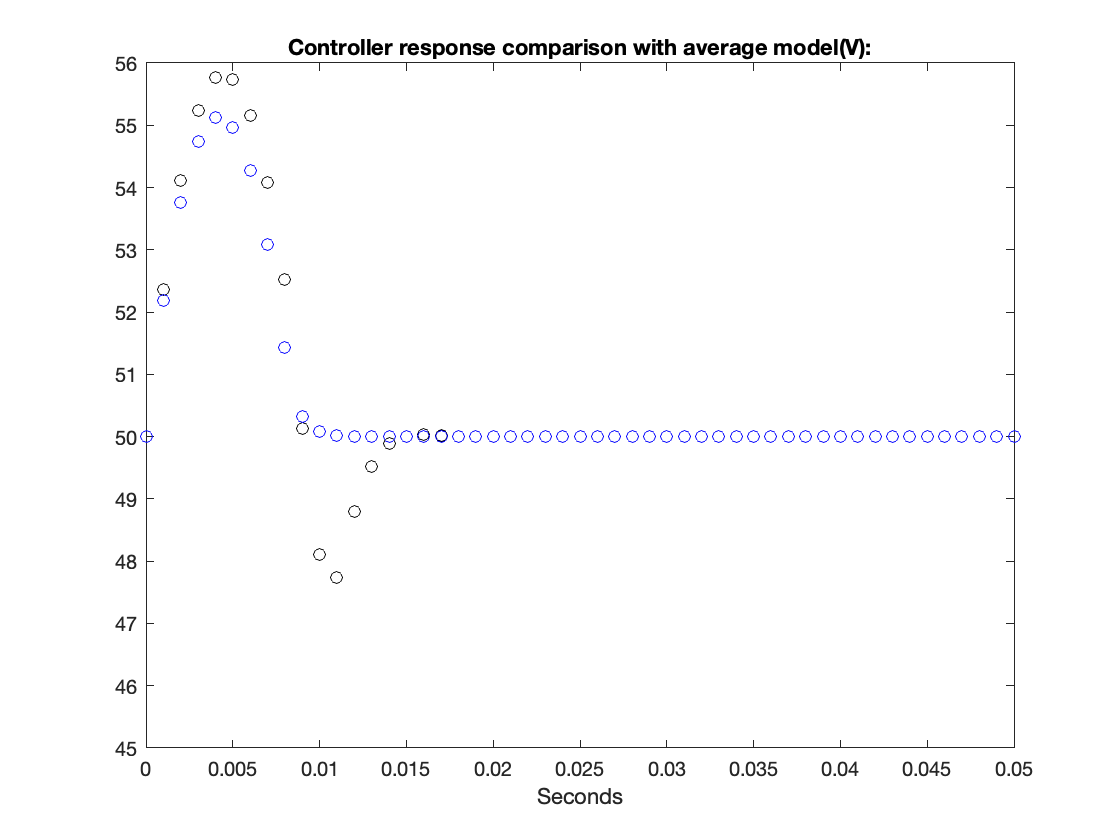

figure
plot(t2,x2(1,:)','o','Color','#EDB120')%Yellow-Discrete free response
hold on
plot(t3,x7(2,:)','o','Color','Black')%Black-Design 1 Average model
plot(t3,x3(2,:)','o','Color','blue')%Blue-Controller design 1 \ no input limit, no decay rate
hold off
title('Controller response comparison with average model(V):')
xlabel('Seconds')
ylim([45 56])
xlim([0 0.05])

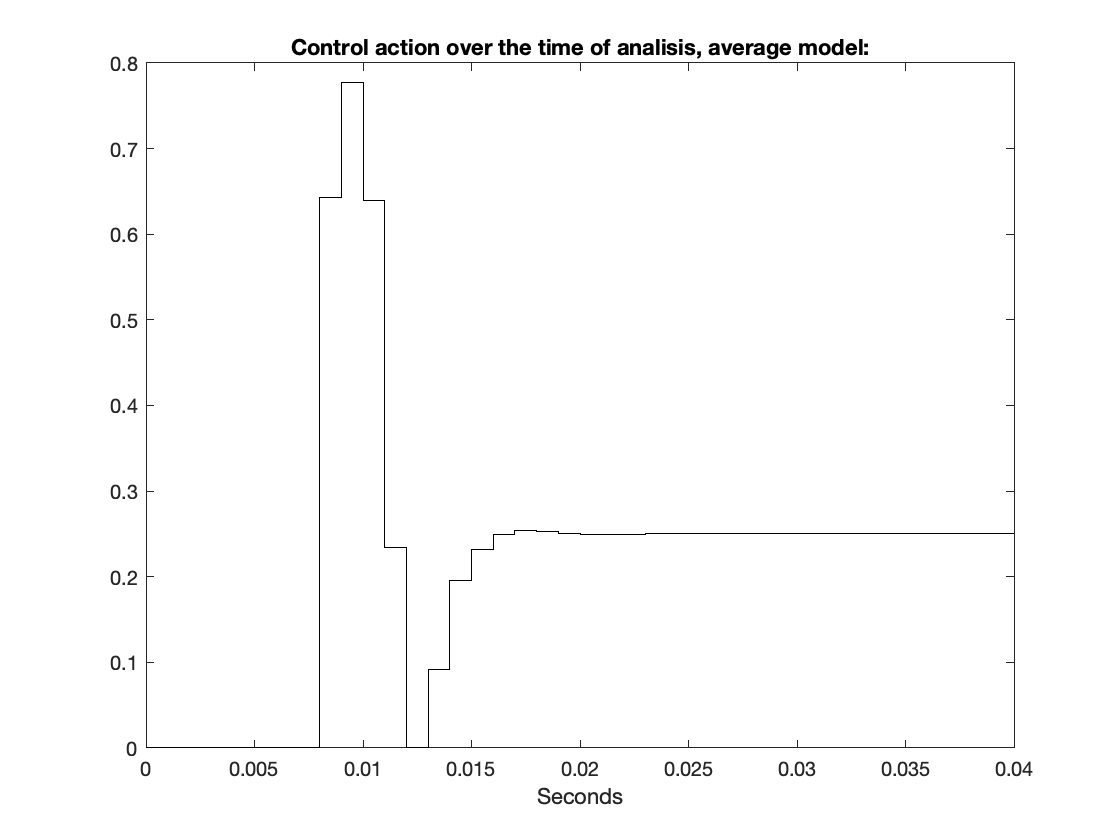

figure
stairs(t4,muT7'/4,'Color','Black')%Black-control action Average model
% For a more comprehensive result, the control action has been fractioned
% to a fourth of the total since, as explained before, we're allowing up to
% four times the response of the controller since it has been averaged to a
% 0.25 trigger time per period.
title('Control action over the time of analisis, average model:')
xlabel('Seconds')
ylim([0 0.80])
xlim([0 0.04])

Max_control_action_average_model=max(muT7/4)

Max_control_action_average_model = 0.7773

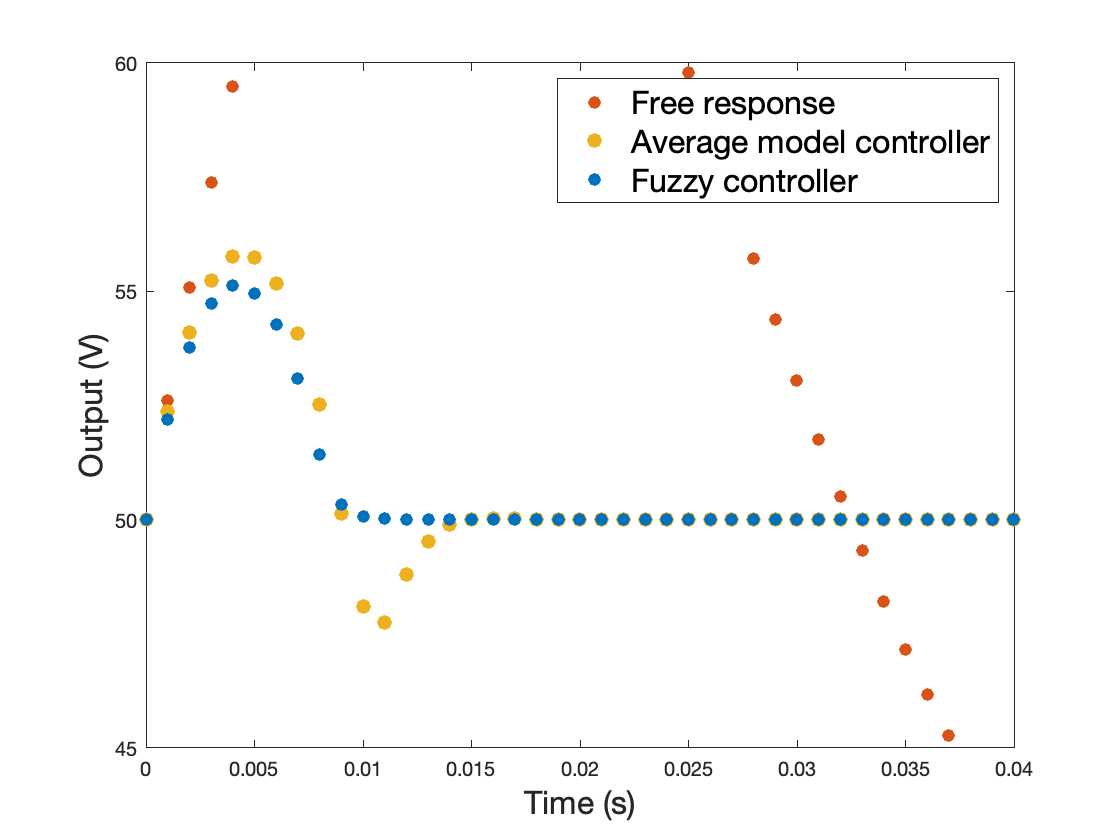

%Now we have a much much faster response for the controlled average model but, 
%as the previous example, it is far from being as fast as the "full" model controlled response.
t3=[0 (1:i)*T];
figure
plot(t2,x2(2,:)','o','Color','#D95319','MarkerFaceColor','#D95319','MarkerSize',6)%Red-Discrete free response
hold on
plot(t3,x7(2,:)','o','Color','#EDB120','MarkerFaceColor','#EDB120','MarkerSize',7)%Yellow-Average model controller
plot(t3,x3(2,:)','o','Color','#0072BD','MarkerFaceColor','#0072BD','MarkerSize',6)%Blue-Controller design 1 \ no input limit, no decay rate
hold off
ylabel({'Output (V)'},'FontSize',16)
xlabel({'Time (s)'},'FontSize',16)
legend({'Free response','Average model controller','Fuzzy controller'},'Location','northeast','FontSize',16)
ylim([45 60])
xlim([0 0.04])